# In the Name of God

close all;
clearvars;
clear;
clc;

## Exc) 3-1

map_set = create_mape_set();

## Exc) 3-2

bit_rate = 1;
msg = 'vw';
[signal, t] = coding_amp(msg, bit_rate, map_set);

1010110110


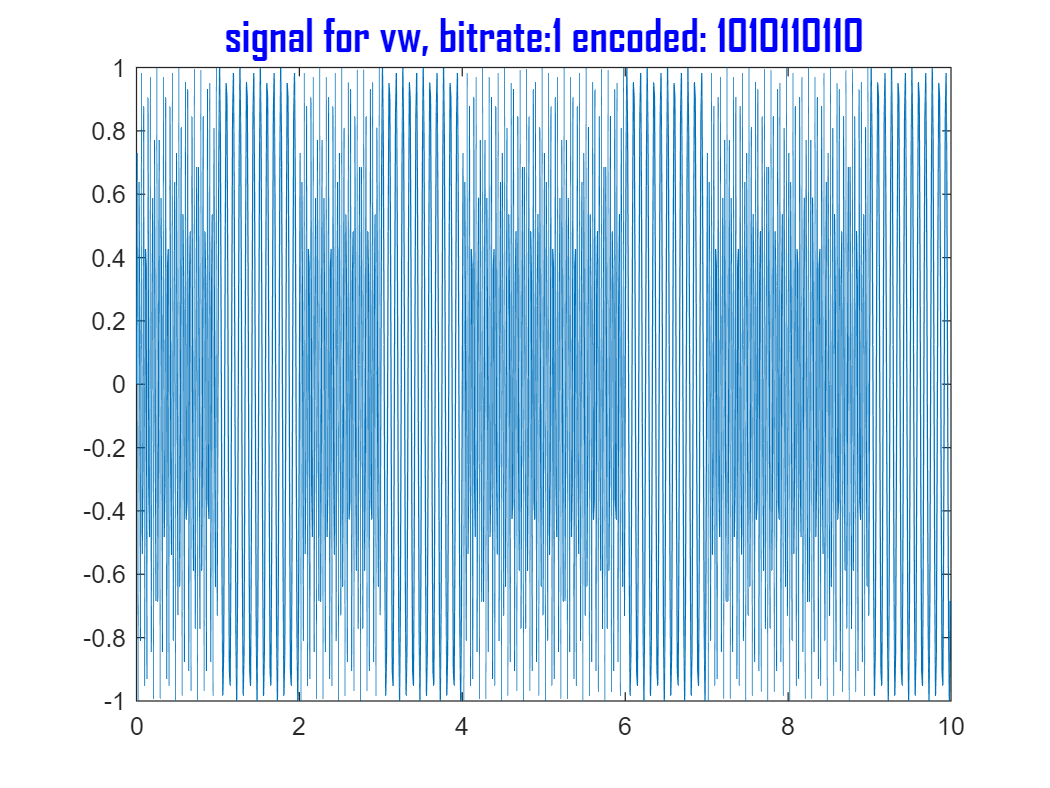

figure('Name', '3-2');
plot(t, signal);
title('signal for vw, bitrate:1 encoded: 1010110110', 'FontSize', 18, 'Color', 'b', 'FontName', 'Agency FB');

## Exc) 3-3

msg = 'signal';

bit_rate = 1;
[signal1, t1] = coding_amp(msg, bit_rate, map_set);

100100100000110011010000001011


bit_rate = 2;
[signal2, t2] = coding_amp(msg, bit_rate, map_set);

100100100000110011010000001011


bit_rate = 3;
[signal3, t3] = coding_amp(msg, bit_rate, map_set);

100100100000110011010000001011


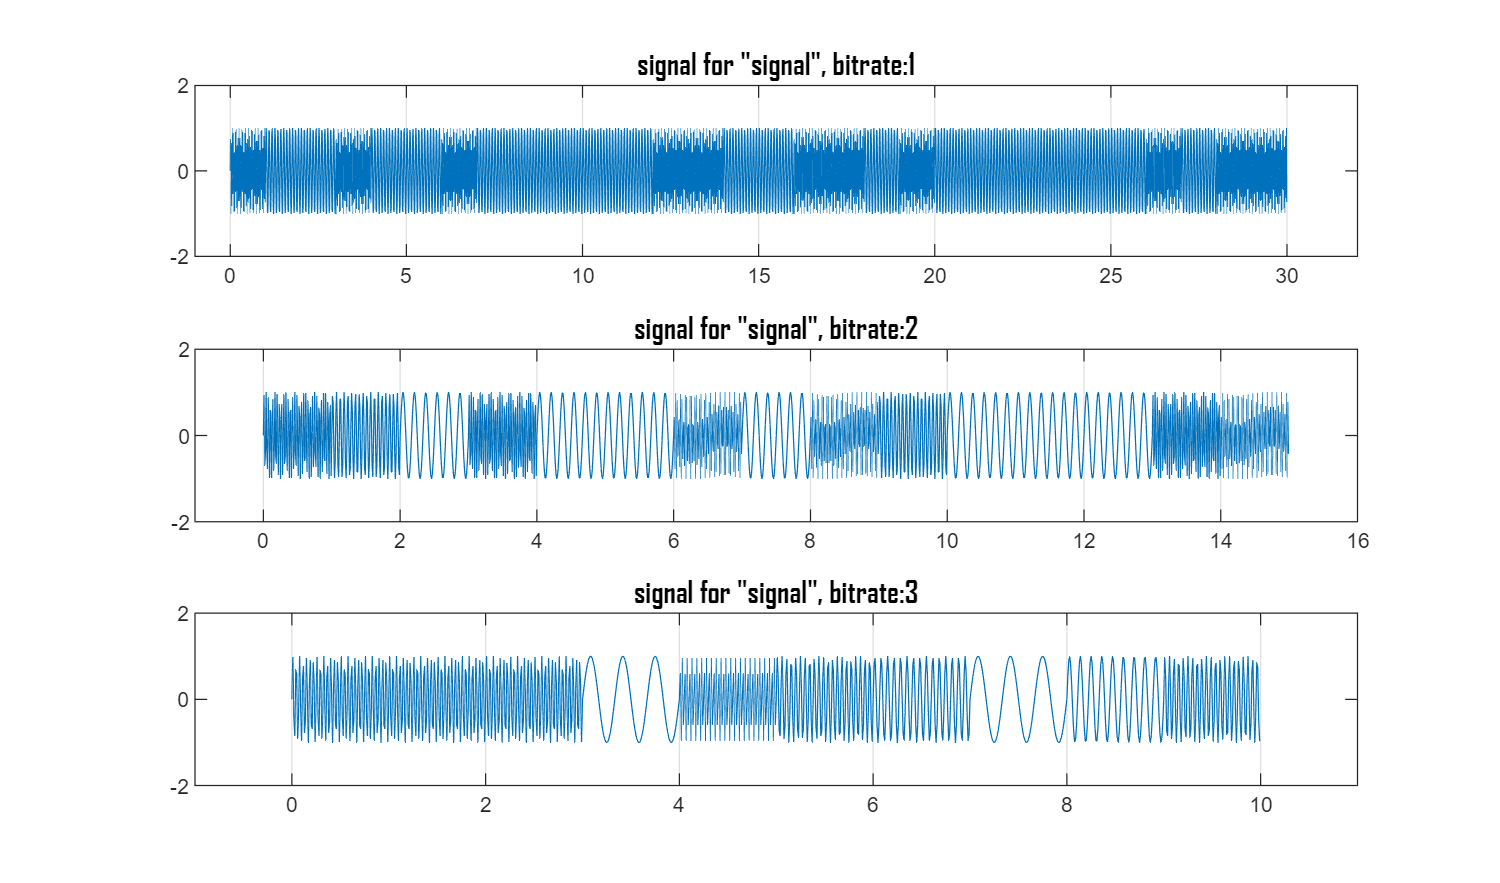

figure('units','normalized','outerposition',[0 0 1 1], 'Name', '3-3')

subplot(3, 1, 1);
plot(t1, signal1);
title('signal for "signal", bitrate:1', 'FontSize', 12, 'FontName', 'Agency FB');

subplot(3,1,2);
plot(t2, signal2);
title('signal for "signal", bitrate:2', 'FontSize', 12, 'FontName', 'Agency FB');

subplot(3,1,3);
plot(t3, signal3);
title('signal for "signal", bitrate:3', 'FontSize', 12, 'FontName', 'Agency FB');

subplot(3, 1, 1)
xlim([-1 32.0])
ylim([-2.00 2.00])
set(gca,'XGrid','on','YGrid','off')

subplot(3,1,2)
xlim([-1 16.0])
ylim([-2.00 2.00])
set(gca,'XGrid','on','YGrid','off')

subplot(3, 1,3)
xlim([-1 11.0])
ylim([-2.00 2.00])
set(gca,'XGrid','on','YGrid','off')

## Exc) 3-4

r1 = decoding_amp(signal1, t1, 1, map_set)

100100100000110011010000001011


r1 = "signal"

r2 = decoding_amp(signal2, t2, 2, map_set)

100100100000110011010000001011


r2 = "signal"

r3 = decoding_amp(signal3, t3, 3, map_set)

100100100000110011010000001011


r3 = "signal"

disp(r1)

signal


disp(r2)

signal


disp(r3)

signal



% CORRECT OUTPUT:
% 100100100000110011010000001011

## Exc) 3-5

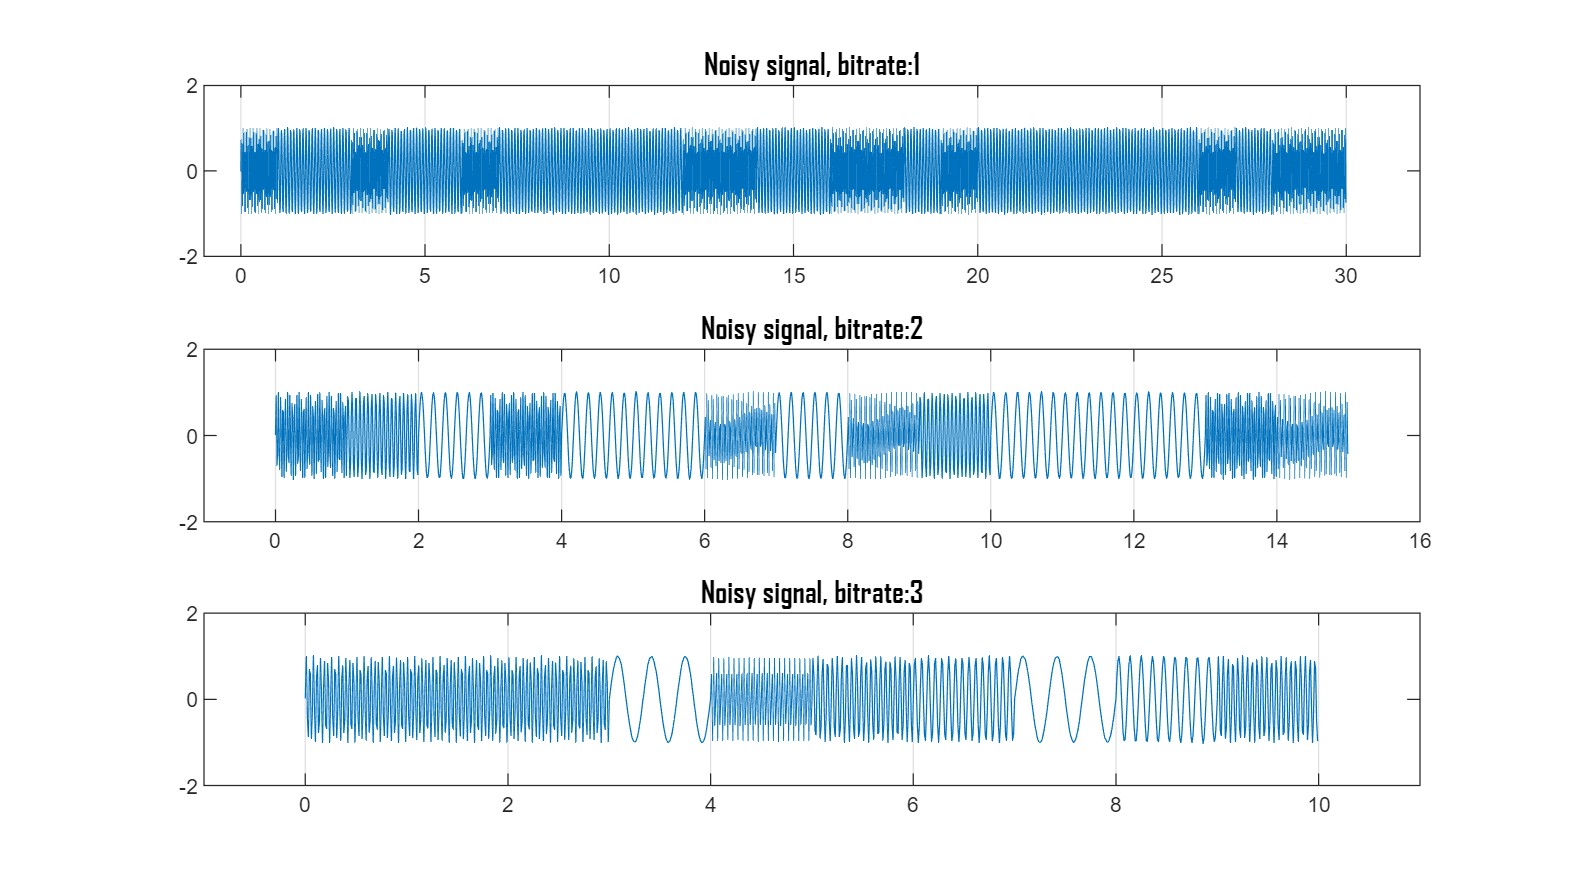

100100100000110011010000001011
100100100000110011010000001011
100100100000110011010000001011
signal
signal
signal
bitRate1 CORRECT
bitRate2 CORRECT
bitRate3 CORRECT


alpha = 0.01;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

## Exc) 3-6.3-7

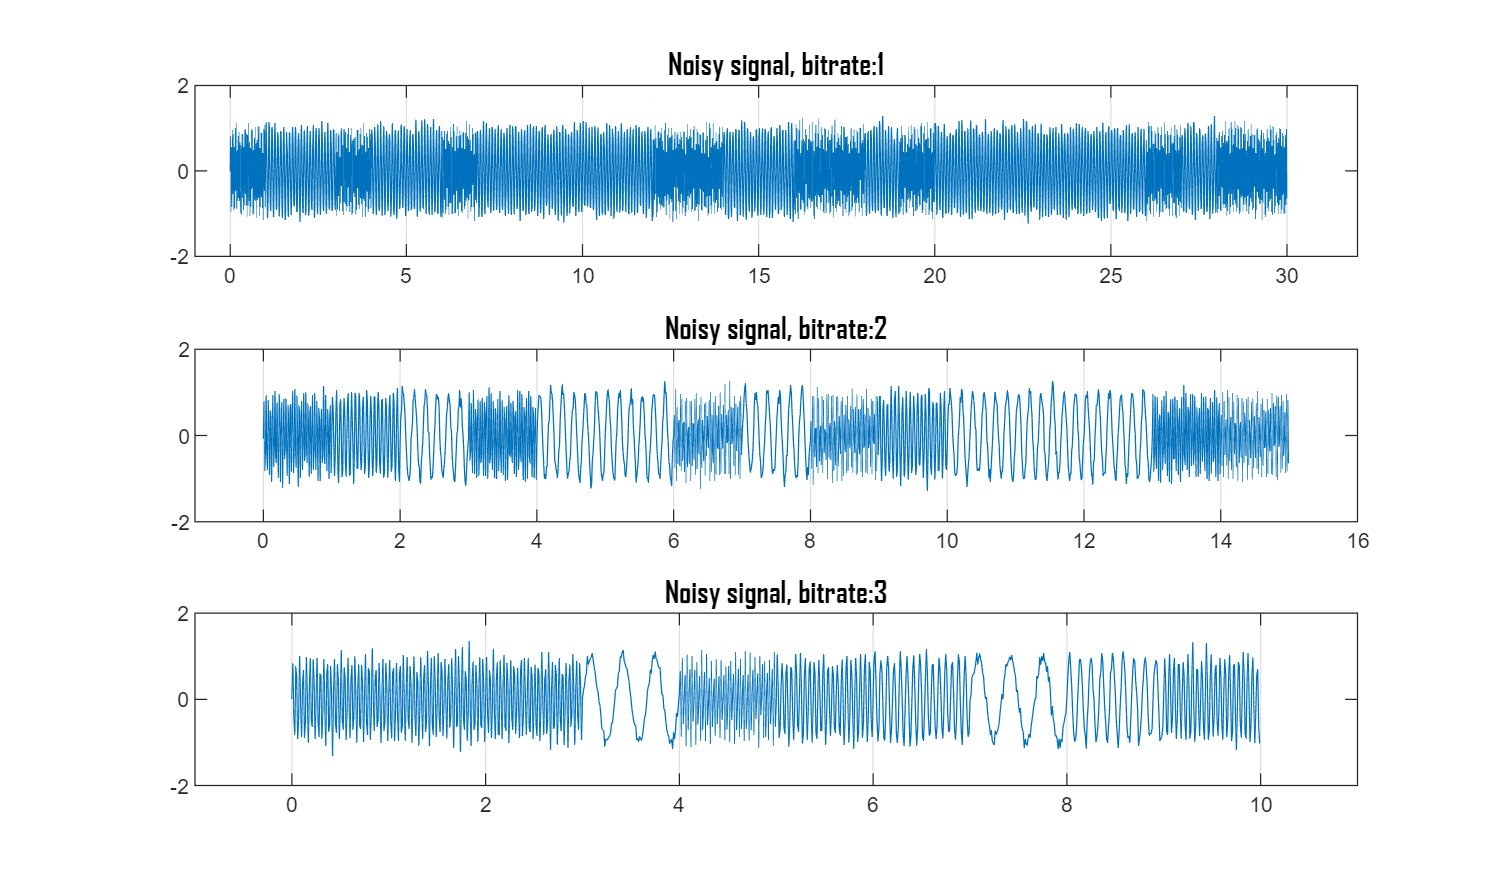

100100100000110011010000001011
100100100000110011010000001011
100100100000110011010000001011
signal
signal
signal
bitRate1 CORRECT
bitRate2 CORRECT
bitRate3 CORRECT


alpha = 0.1;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

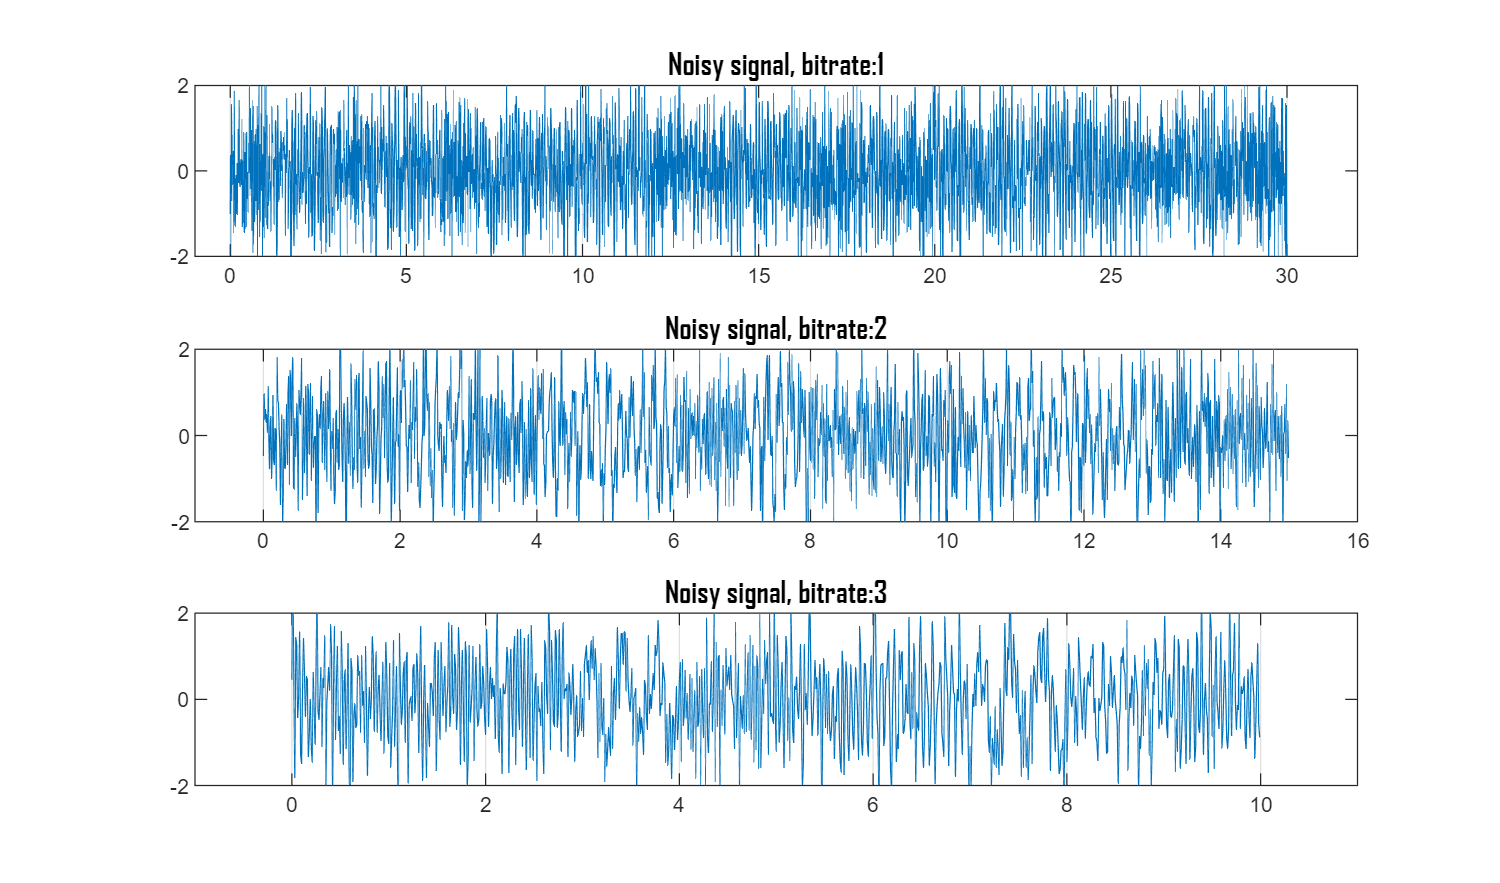

100100100000110011010000001011
100100100000110011010000001011
100100100000110011010000001011
signal
signal
signal
bitRate1 CORRECT
bitRate2 CORRECT
bitRate3 CORRECT


alpha = 0.7;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

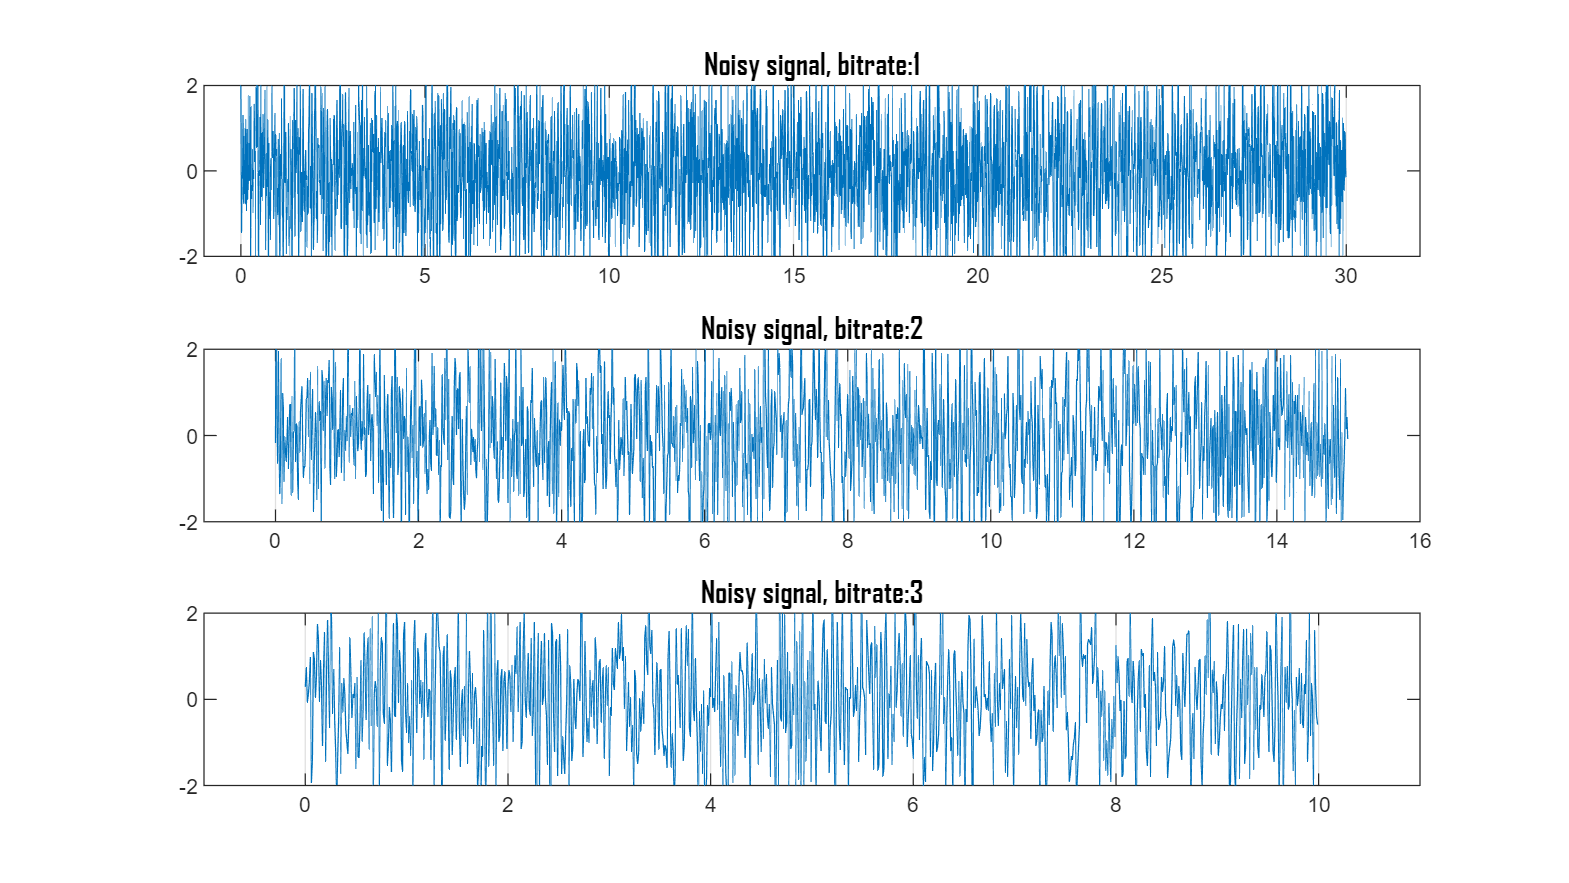

100100100000110011010000001011
100100100000110011010000001011
100100100000110011010000001011
signal
signal
signal
bitRate1 CORRECT
bitRate2 CORRECT
bitRate3 CORRECT


alpha = 1;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

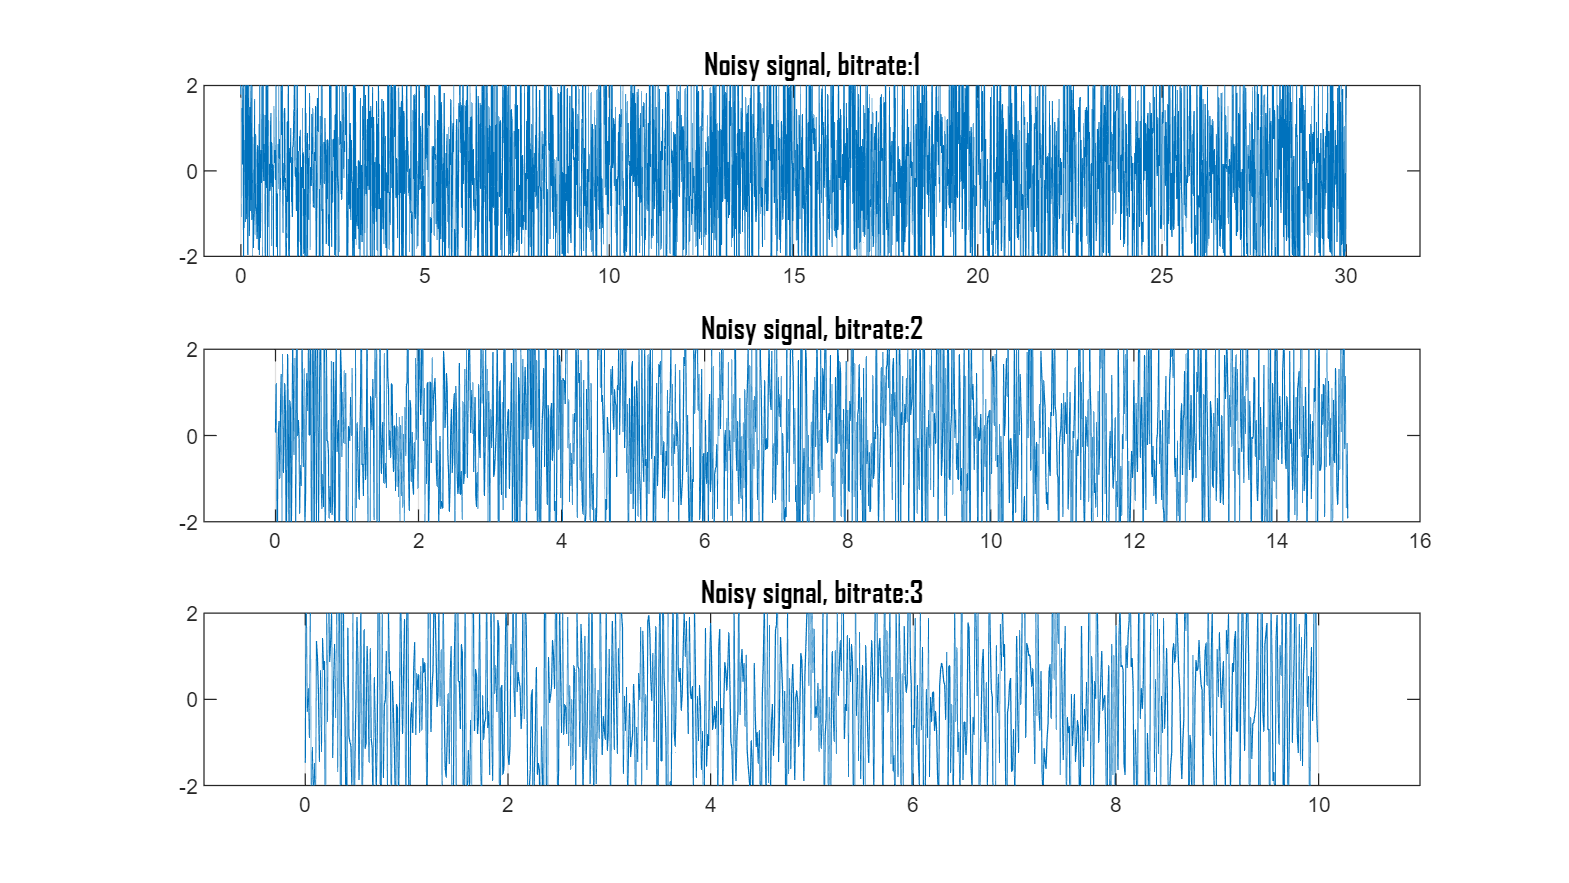

100100100000110011010000001011
100100100000110011010000001011
100100100000110011010000001011
signal
signal
signal
bitRate1 CORRECT
bitRate2 CORRECT
bitRate3 CORRECT


alpha = 1.5;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

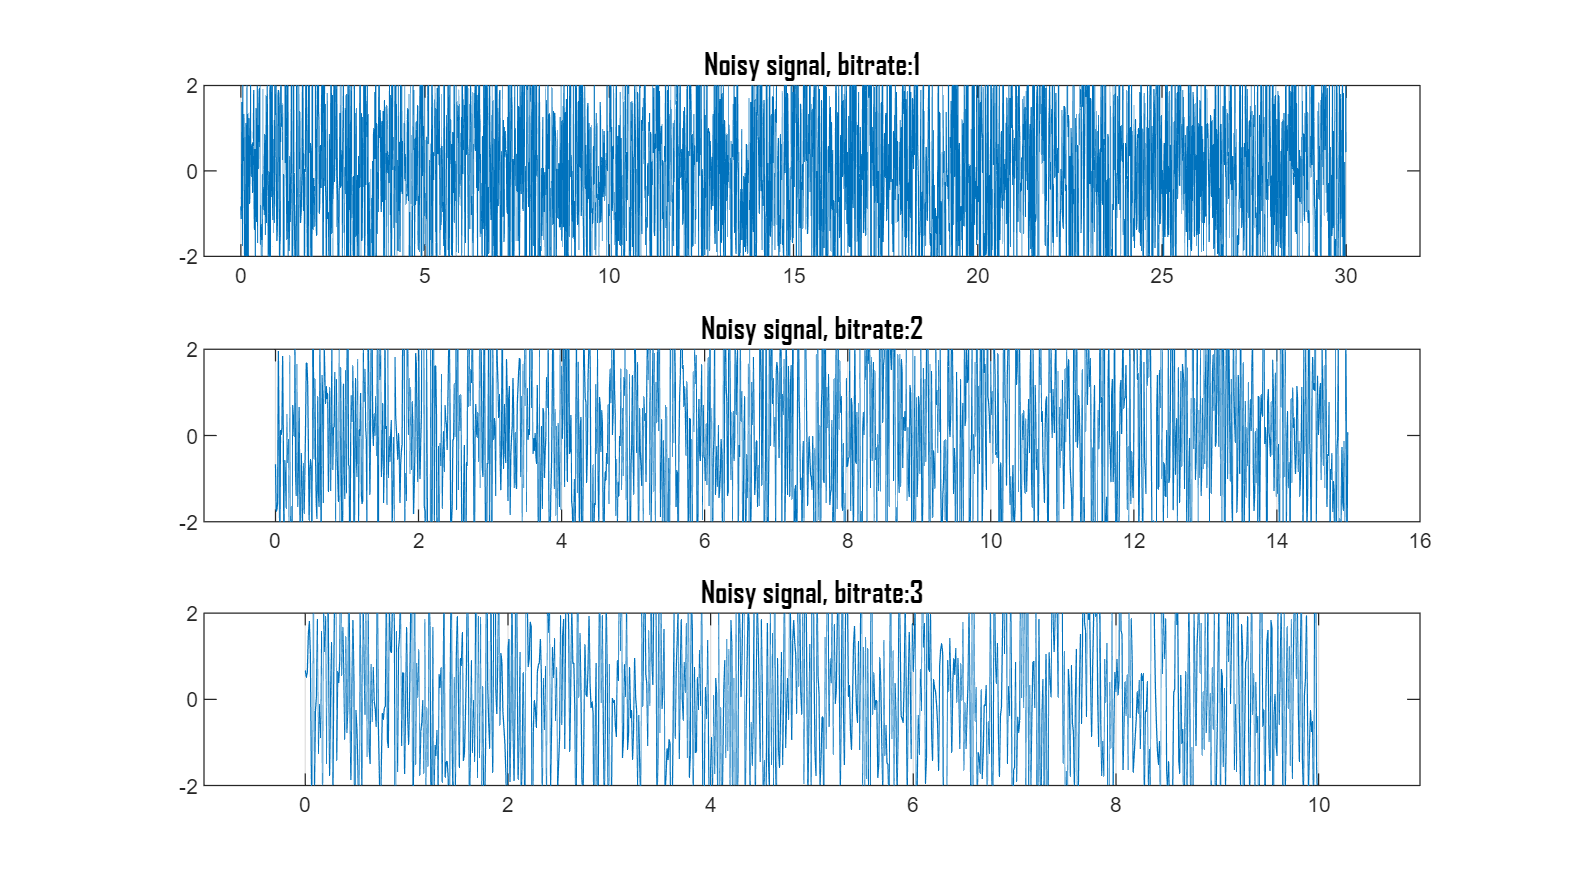

100100100000100011010001011011
100100100000110011010000001011
100100100000110011010000001011
sienc.
signal
signal
bitRate1 INCORRECT
bitRate2 CORRECT
bitRate3 CORRECT


alpha = 1.75;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

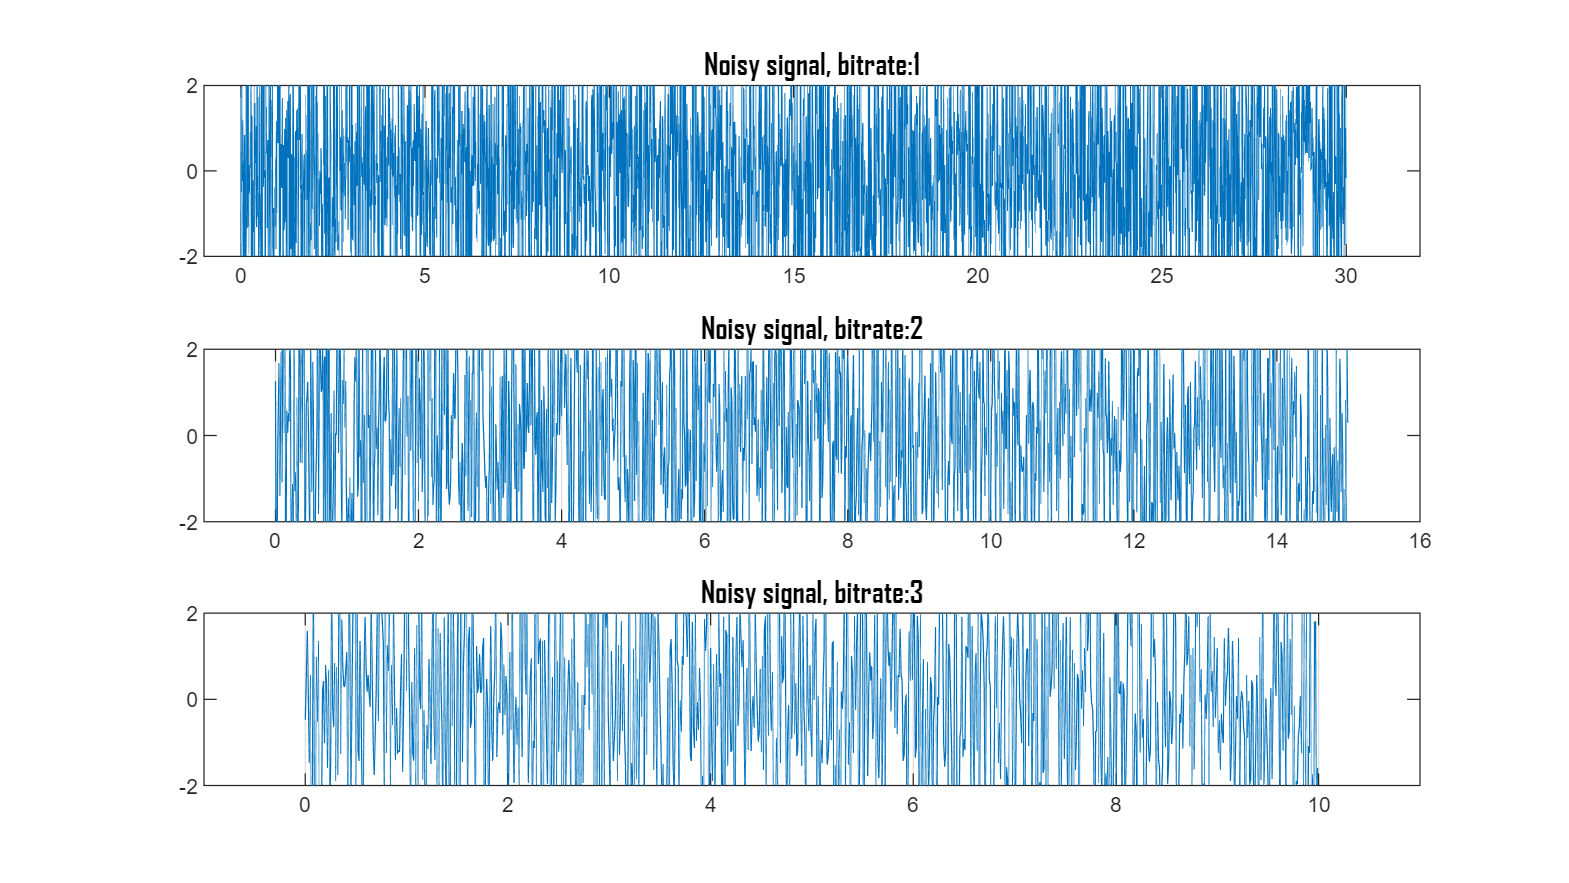

000100100010110000010000001011
100100100000010011010100001000
100100100010100110010111001000
ciwbal
sicnii
siuzoi
bitRate1 INCORRECT
bitRate2 INCORRECT
bitRate3 INCORRECT


alpha = 2;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

## Functions:

function evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg)
    noise1 = alpha * randn(1, length(signal1));
    noise2 = alpha * randn(1, length(signal2));
    noise3 = alpha * randn(1, length(signal3));
    
    noisy_signal1 = signal1 + noise1;
    noisy_signal2 = signal2 + noise2;
    noisy_signal3 = signal3 + noise3;

    figure('units','normalized','outerposition',[0 0 1 1], 'Name', '3-3')

    subplot(3,1,1);
    plot(t1, noisy_signal1);
    title('Noisy signal, bitrate:1', 'FontSize', 12, 'FontName', 'Agency FB');
    
    subplot(3,1,2);
    plot(t2, noisy_signal2);
    title('Noisy signal, bitrate:2', 'FontSize', 12, 'FontName', 'Agency FB');
    
    subplot(3,1,3);
    plot(t3, noisy_signal3);
    title('Noisy signal, bitrate:3', 'FontSize', 12, 'FontName', 'Agency FB');
    
    subplot(3,1,1)
    xlim([-1 32.0])
    ylim([-2.00 2.00])
    set(gca,'XGrid','on','YGrid','off')
    
    subplot(3,1,2)
    xlim([-1 16.0])
    ylim([-2.00 2.00])
    set(gca,'XGrid','on','YGrid','off')
    
    subplot(3,1,3)
    xlim([-1 11.0])
    ylim([-2.00 2.00])
    set(gca,'XGrid','on','YGrid','off')

    r1 = decoding_amp(noisy_signal1, t1, 1, map_set);
    r2 = decoding_amp(noisy_signal2, t2, 2, map_set);
    r3 = decoding_amp(noisy_signal3, t3, 3, map_set);

    disp(r1);
    disp(r2);
    disp(r3);

    if strcmp(r1, msg)
        disp("bitRate1 CORRECT");
    else
        disp("bitRate1 INCORRECT");
    end

    if strcmp(r2, msg)
        disp("bitRate2 CORRECT");
    else
        disp("bitRate2 INCORRECT");
    end

    if strcmp(r3, msg)
        disp("bitRate3 CORRECT");
    else
        disp("bitRate3 INCORRECT");
    end

end

function bin_representation = find_nearest(bit_rate, res)
    max = 2 ^ bit_rate;
    min_diff = 1000;
    best_guess = 0;
    step = 49/(max *2);

    
    for i = 0:max - 1
        freq = round(step * (2*i + 1));
        diff = abs(res - freq);
        if diff < min_diff
            min_diff = diff;
            best_guess = i;
        end
    end
    bin_representation = dec2bin(best_guess, bit_rate);
end

function output = decoding_amp(signal, tt, bit_rate, map_set)
    time = length(tt)/100;
    t = -50:1:49;
    coded_signal = '';
    for i = 1 : time
        s = signal((i-1)*100 + 1 : i*100);
        fourier = abs(fftshift(fft(s)));
%         plot(t, fourier);
        [max_value,index] = max(fourier(51:100));
        coded_signal = [coded_signal, find_nearest(bit_rate, index - 1)];
    end
    output = "";
    disp(coded_signal);
    for i = 1 : length(coded_signal) / 5
        bin = coded_signal((i-1)*5+1:i*5);
        for j = 1:32
            if(strcmp(map_set(2,j), bin))
                output = output + map_set(1,j);
                break;
            end
        end
    end
end

function [signal, t_totall] = coding_amp(msg, bit_rate, map_set)

    coded_signal = "";
    for i = 1 : length(msg)
        for j = 1 : 32
            if strcmp( msg(i), map_set(1, j))
                coded_signal = coded_signal + map_set(2, j);
                break
            end
        end
    end

    while rem(strlength(coded_signal), bit_rate) ~= 0
        coded_signal = coded_signal + '0';
    end
    coded_signal = convertStringsToChars(coded_signal);

    max = 2 ^ bit_rate;
    step = 49/(max *2);
    
    t_start = 0;
    t_end = 1;
    fs = 100;
    ts = 1/fs;
    
    t_final = length(coded_signal) / bit_rate;
    
    t_totall = 0:ts:t_final-ts;
    signal = [];
    for i = 1 : length(coded_signal) / bit_rate
        t = t_start:ts:t_end-ts;
        t_start = t_start + 1;
        t_end = t_end + 1;
        val = bin2dec(coded_signal((i - 1)*bit_rate+1 :i*bit_rate));
        freq = round(step * (2*val + 1));
%         disp(freq);
        s = sin(2 * pi * freq * t);
        signal = [signal , s];
    end
    disp(coded_signal);   
end

function map_set = create_mape_set()
    map_set = cell(2, 32);
    
    i = 1;
    for letter = 'a' : 'z'
        map_set{1, i} = letter;
        map_set{2, i} = dec2bin(i - 1, 5);
        i = i + 1;
    end
    
    map_set{1, 27} = ' ';
    map_set{1, 28} = '.';
    map_set{1, 29} = ',';
    map_set{1, 30} = '!';
    map_set{1, 31} = ';';
    map_set{1, 32} = '"';
    
    map_set{2, 27} = '11010';
    map_set{2, 28} = '11011';
    map_set{2, 29} = '11100';
    map_set{2, 30} = '11101';
    map_set{2, 31} = '11110';
    map_set{2, 32} = '11111';
end